**Implementation of :**

### ***A Single Backlit Image Enhancement Method For Improvement Of Visibility Of Dark Part***

**Published in: 2021 IEEE International Conference on Image Processing (ICIP)**

**Authors: **

[Masato Akai](https://ieeexplore.ieee.org/author/37089384056)

Yamaguchi University

[Yoshiaki Ueda](https://ieeexplore.ieee.org/author/37075106000)

Fukuoka University

[Takanori Koga](https://ieeexplore.ieee.org/author/37889504000)

Kindai University

[Noriaki Suetake](https://ieeexplore.ieee.org/author/37285071000)

Yamaguchi University

**TERM PROJECT**

**Name : Ifrah Asif Hasan (Indian Institute of Technology, Kharagpur)**

**Roll Number : 19EE38028**

Original Image taken as rgb with size of :**720x960.**

I_rgb = imread('SunsetGirl.jpg');

Converting rgb to gray using **0.3*r + 0.587*g + 0.11*b.**

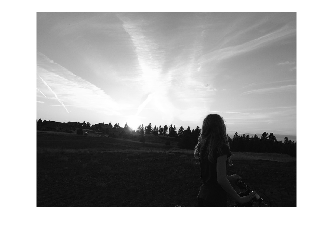

I = rgb2gray(I_rgb);
imshow(I)

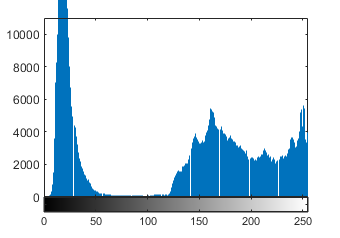

imhist(I)

Using *Gamma Correction* with **Gamma = 0.5**.

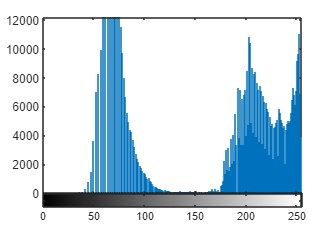

I_Gamma = imadjust(I,[],[],0.5);
imhist(I_Gamma)

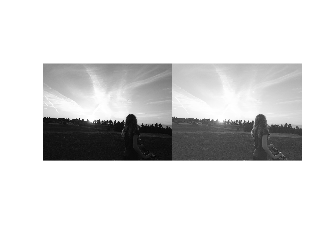

imshowpair(I,I_Gamma,"montage")

Using *Histogram Equilization*.

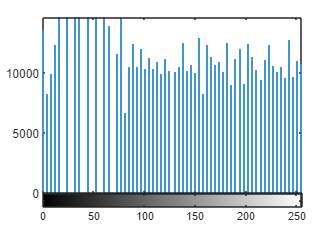

I_HisEq = histeq(I);
imhist(I_HisEq)

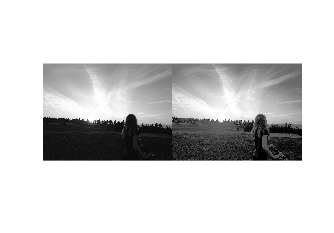

imshowpair(I,I_HisEq,"montage")

Blending them by *Alpha-Blending Method*; **Alpha is 0.2** .

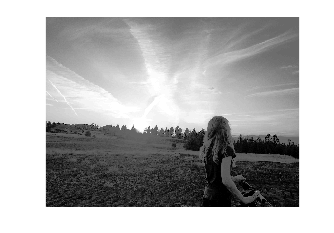

Ibg = I_HisEq;
Ifg = I_Gamma;

if length(size(Ibg))==3
        Ibg=rgb2gray(Ibg);
end
if length(size(Ifg))==3
        Ifg=rgb2gray(Ifg);
end

alpha = 0.2;

[row,col] = size(Ibg);
O = zeros(row,col);
O = uint8(I);
for i = 1:row
    for j = 1:col
        O(i,j) = alpha * Ibg(i,j) + (1 - alpha) * Ifg(i,j);
    end
end


imshow(Ibg);

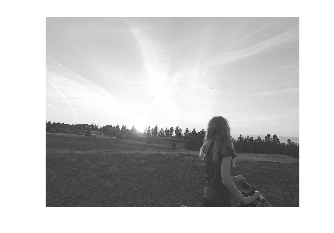

imshow(Ifg);

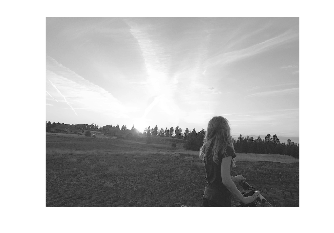

imshow(O);

Histogram : Threshold is calculated using *Otsu's Method* and shown with a bright red line.

**Threshold is 0.4157.**

imhist(O)
t = otsuthresh(histcounts(I,-0.5:255.5))

t = 0.4157

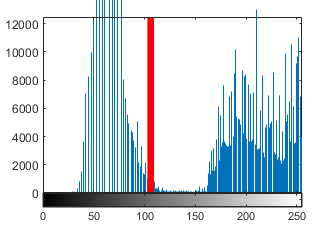

hold on
plot(255*[t t], ylim, 'r', 'LineWidth', 5)
hold off

A = imbinarize(O,t);

Using *Guided Filter* on A with I as the guide,Taking **NeighborhoodSize as 41(2r +1) r = 20 .**

Without specifying the size, a better result is observed.

W = imguidedfilter(A,I,"NeighborhoodSize",[41 41]);
X = imcomplement(W);

Converting into proper format.

W = uint8(W);
X = uint8(X);

Constructing the Final RGB Image

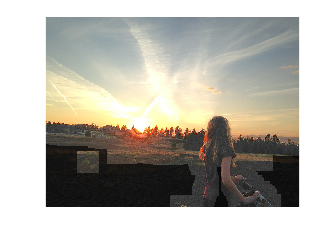

O_Temp = W.*O + X.*I;

O_rgb = I_rgb.*(O_Temp./I);
imshow(O_rgb)

Calculation of **Naturalness Image Quality Evaluator (NIQE)**.

We get a nearly equal result as compared to the Research Paper : **Paper --> 2.31 Our Result --> 2.2789**

niqe(O_rgb)

ans = 2.2789

Calculation of **Lightness Order Error (LOE) **.

We get a nearly equal result as compared to the Research Paper : **Paper --> 134 Our Result --> 142.0537**

[N M n] = size (I_rgb);

L = max(I_rgb,[],3);
Le = max(O_rgb,[],3);

r = 50 / min (M,N);
Md = round(M*r);
Nd = round(N*r);
Ld =imresize(L,[Nd Md]);
Led =imresize(Le,[Nd Md]);

RD = zeros (Nd,Md);
size (RD);

for y = 1:Md
    for x = 1:Nd

        E = xor((Ld(x,y)>=Ld(:,:)),(Led(x,y)>=Led(:,:)));
        RD(x,y) = sum(E(:));

    end
end
LOE = sum(RD(:))/(Md*Nd)

LOE = 142.0537